# Extra 1: Uncertainties Through 1-Parameter Graphical Method

In the tutorial examples, the uncertainties associated to a model's parameters were estimated by using calculating the coviance matrix. Sometimes these matrices aren't easily calculable, or sometimes even singular. An alternative method to uncertainty estimation is based on graphical inspection of the$\chi^2$ function, hence the name "graphical method". This notebook will focus on using the graphical method on a model with a single parameter. In this case, the data is of an exponential distribution. 

First we're going to calculate the uncertainties from the covariance method using the jocobian. The graphical method does not make use of the Jacobian or curvature matrix. We just computed them to compare the resulting parameter uncertainty with the following.

## Read In Raw Data:

Follow the data reading procedure as normal and make a simple plot of the data

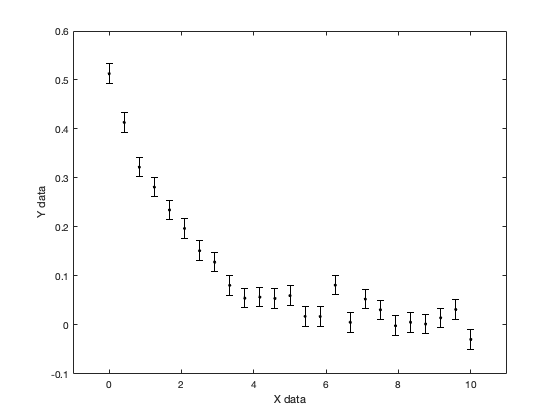

data_path = '~/tutorialSims/phys3007_matlab_tutorial/data/';                           
file_name = 'exp_1param.txt';
file_path = strcat(data_path, file_name);
data = dlmread(file_path);    

% split the data into vectors
x_data = data(:, 1);
y_data = data(:, 2);
y_err = data(:, 3);

% plot the data
fig1 = figure;
ax1 = axes(fig1);
errorbar(ax1, x_data, y_data, y_err, 'k.')
ax1.XLim = [-1 11];
xlabel('X data')
ylabel('Y data')

Now we're going to define our 1-parameter function. We'll use the single parameter to represent both the normalization of the function, as well as it's argument coefficent. 

 
$$f(x| a_{1}) = a_{1} \cdot \text{exp}(-a_{1} \cdot x)
$$


Again, we're following the original method of fitting and covriance calculation. Since our model is 1-parameter we expect our matrix to be 1X1 (a single scalar) equal to the variance (i.e. the square of the standard deviation).

% define the fittype for the model function
ft = fittype('a*exp(-a*x)');

% perform the chi-squared minimization
[f, gof, fit_output] = fit(x_data, y_data, ft, 'Weights', y_err.^(-2));


% extract the weighted Jacobian matrix of the model fit
J = fit_output.Jacobian;

% compute the curvature and covariance matrices
curvature_matrix = J' * J;
covariance_matrix = inv(curvature_matrix);

The uncertainty using this method gives $\sigma_{a}^{cov} = 1.511 \times 10^{-2}$. Next, we'll inspect the $\chi^2

$ function as a function of our parameter around the best fit value. Do do so, we just loop over the parameter values and recalculate the $\chi^2$ function.

% create a vector of parameter values around the best fit value
a_vec = linspace(f.a - 0.02, f.a + 0.02, 1000);

% instantiate a vector for chi-squared values and use a loop to compute
% the value for each parameter value in a_vec
chi2 = zeros(1, 1000);
for i = 1:1000
    chi2(i) = sum( (y_data - a_vec(i)*exp(-a_vec(i)*x_data)).^2 ./ y_err.^2);
end

We will plot the $\chi^2$ function, keeping all of the x, y, and σy data points fixed and varying only the parameter value. Plot the function in the vicinity of the best fit parameter value. The graphical method states that the uncertainty on the best fit parameter is found by looking at the value $\chi^2 =\chi^2_{min} + 1$. The distance from between $a(\chi^2_{min})$ and $a(\chi^2_{min} + 1)$is equal to the error $\sigma_{a}^{graph}$.

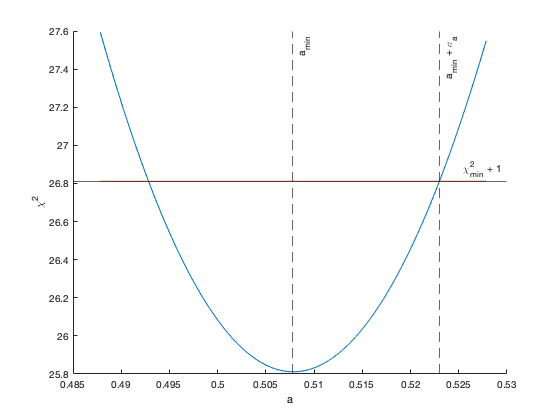

% plot chi squared as a function of the parameter value
fig2 = figure;
ax2 = axes(fig2);
hold on
plot(a_vec, chi2)
plot(a_vec, (gof.sse+1)*ones(1, numel(a_vec)))
xlabel('a')
ylabel('\chi^2')
y1 = yline(26.8118,'-','\chi^2_{min} + 1');
x1 = xline(0.5078,'--','a_{min}');
x2 = xline(0.523,'--','a_{min} + \sigma_{a}');